# Reconocimiento de patrones en curvas mediante el SOM 

#### Trabajo final de Redes Neuronales y Aprendizaje Estadístico

**Docente: **Pedro J. Zufiria.

**Autor: **Carlos Eduardo Meneses Marín.

**Fecha de entrega:** 20 - 03 - 2020

*Nota para la ejecución de este LiveScript:* por favor, asegúrese de que su *current folder* de Matlab sea la carpeta en la que se encuentre este fichero. Además, verifique que la carpeta *Data* también está en su *current folder* ya que los datos que contienen son llamados mediante el *path* relativo `'./Data/'`. Además, es necesario disponener de los siguientes *toolboxes*:

- *Statistics and Machine Learning Toolbox*.

- *Deep Learning Toolbox.*

## Introducción

Poder reconocer y establecer patrones a partir de movimientos es una capacidad tecnológica muy desarrollada en los últimos años. Es usada en el mundo de las videoconsolas como la *Wii*, la *PlayStation5* o el mismo teléfono móvil. Este trabajo tiene por objetivo reconocer y distinguir entre diferentes movimientos realizados con el teléfono móvil, como un círculo a derechas, un círculo a izquierdas o una línea recta. Los medios para alcanzar dicho propósito son un *dataset* de casi 400 movimientos de los tipos descritos, registrados mediante el acelerómetro del móvil. Como herramienta de resolución, uso un mapa auto-organizado de Kohonen.

La motivación de este trabajo se encuentra en las grandes posibilidades del reconocimiento de movimientos para el desarrollo de tecnologías para la accesibilidad y movilidad de personas con discapacidad, más allá de su actual expansión en el mundo de los videojuegos. Por ejemplo, en el desarrollo de dispositivos inalámbricos que una persona con parálisis motriz pueda usar en cualquier extremidad del cuerpo, que conserve su movilidad, y reconozca patrones que le permitan controlar un móvil, un ordenador, o quizás un exoesqueleto.

## La base de datos

Los datos se recogieron mediante en el acelerómetro de mi móvil personal, en particular, limitándome al plano de una mesa y seleccionando sólo las componentes involucradas: la $x$ y la $y$ . Los movimientos fueron grabados en bloques, en los que procuraba que un movimiento completo durase en torno a 1 segundo. La tasa de muestreo es de, aproximadamente, 60 datos por segundo. De esta forma, para extraer las observaciones individuales de las curvas, sólo hay que dividir los datos de cada bloque en trozos iguales. En total, grabé cuatro tipos de movimientos, a saber:

- Círculos a derechas (radio pequeño, mediano y grande).

- Círculos a izquierdas (radio pequeño, mediano y grande).

- Movimientos rectilíneos (hasta 4 direcciones diferentes).

- Movimientos indefinidos (no serán tenidos en cuenta sino hasta el final de esta memoria).

A continuación, cargamos los datos y graficamos las aceleraciones de todos los bloques algunas de las las curvas:

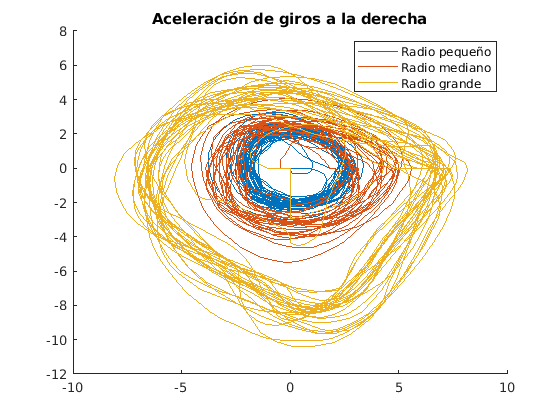

clear all
close all

% Establecemos una semilla para reroducibilidad
rng(100)

% Conjuntos de curvas a cargar (círculos y rectas). 
s = {'CD2', 'CD3', 'CD4', 'CI2', 'CI3', 'CI4', 'R2', 'R3', 'R4', 'R5'};
maxLen = 40; % Longitud de cada curva.

% Ejecutamos la función especialmente definida para cargar los datos.
[dataTrain, tagTrain, dataTest, tagTest] = load_data(s, maxLen);

% Aceleración de giros a la derecha
figure()
hold on
plotAcceleration('CD2', '-')
plotAcceleration('CD3', '-')
plotAcceleration('CD4', '-')
title('Aceleración de giros a la derecha')
legend('Radio pequeño', 'Radio mediano', 'Radio grande')
hold off

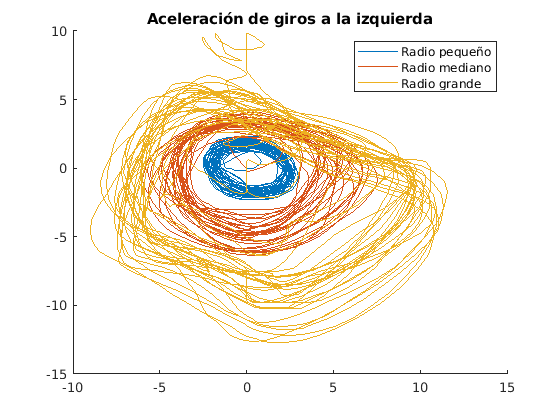


% Aceleración de giros a la izquierda
figure()
hold on
plotAcceleration('CI2', '-')
plotAcceleration('CI3', '-')
plotAcceleration('CI4', '-')
title('Aceleración de giros a la izquierda')
legend('Radio pequeño', 'Radio mediano', 'Radio grande')
hold off

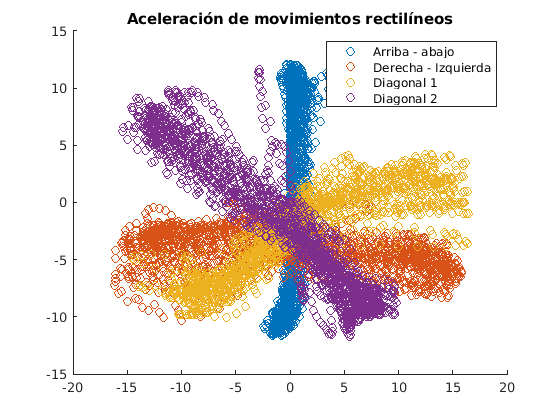


% Aceleración de movimientos rectilíneos
figure()
hold on
plotAcceleration('R2', 'o')
plotAcceleration('R3', 'o')
plotAcceleration('R4', 'o')
plotAcceleration('R5', 'o')
title('Aceleración de movimientos rectilíneos')
legend('Arriba - abajo', 'Derecha - Izquierda', 'Diagonal 1', 'Diagonal 2')
hold off

Ahora, graficamos tres ejemplos concretos de los círculos y las rectas. Nótese que se ha calculado la curvatura de cada movimiento, siguiendo la ecuación de *Curvas y Superficies. Definiciones, teoremas y resultados* de Juan de Burgos Román:

$k = \frac{x'(\lambda)y''(\lambda)-x''(\lambda)y'(\lambda)}{[x'(\lambda)^2 + y'(\lambda)^2]^{3/2}}$,

donde la curva viene definida por $x = x(\lambda),\ y=y(\lambda)$ y $\lambda$ es el parámetro temporal.

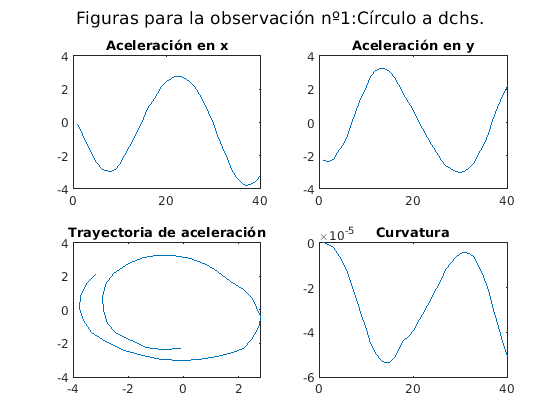

% Plots de un círculo a derechas
n = 1;
figure()
plotExample(dataTrain, tagTrain, n)

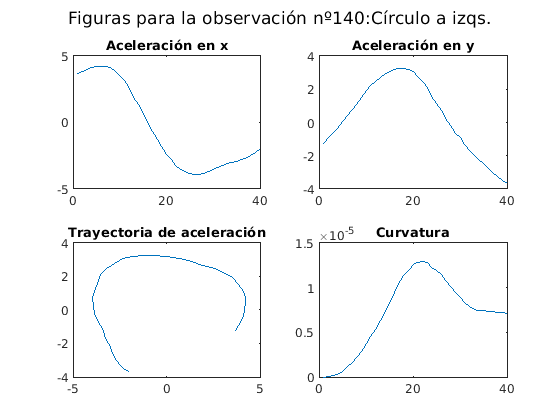


% Plots de un círculo a izquierdas
n = 140;
figure()
plotExample(dataTrain, tagTrain, n)

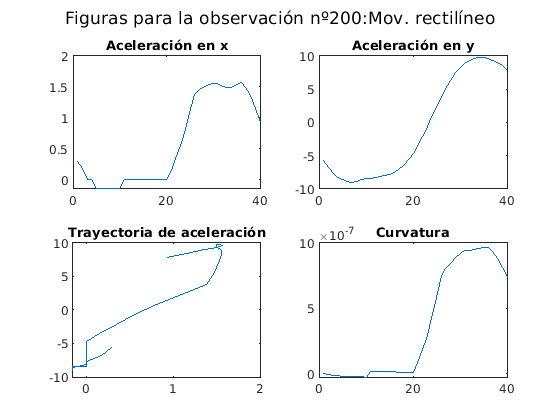


% Plots de un movimiento rectilíneo
n = 200;
figure()
plotExample(dataTrain, tagTrain, n)

Se puede observar que los ejemplos no son perfectos: hay círculos con algo más de una vuelta, otros sin llegar a terminar una vuelta y las rectas tienen imperfecciones en los extremos. Estos defectos están íntimamente ligados con la forma de separar cada obsevación de un bloque o apilamiento de observaciones y con la recolección de los datos, que puede verse en el siguiente [video de Youtube](https://youtu.be/vseVqCDM7bo).

## Procedimiento de resolución

En primer lugar, hago uso de una separación inteligente de los datos: un $80\%$ de aprendizaje y un $20\%$ de test. A continuación, entreno un mapa auto-organizado de Kohonen (Self Organizing Map, SOM) de $8 \times 8$ neuronas, evaluo la separación de las distintas categorías. Tras comprobar que los resultados son satisfactorios, asigno a cada neurona entrenada la clase o tipo de movimiento que más representa. De esta forma, he construido un clasificador que puede ser evaluado sobre el conjunto de test.

## Implementación del SOM

La siguiente caja de código implementa el SOM. 

dimx = 8; % Neurona en el eje x.
dimy = 8; % Neuronas en el eje y.
dimxy = dimx * dimy; % Cantidad de neuronas en total.

net = selforgmap([dimx dimy]);
net = train(net,dataTrain); % Entrenamiento de la red.

Las neuronas de la red se distribuyen según una topología hexagonal, como puede apreciarse en la figura a continuación, en la que las neuronas son los polígonos azules grisáceos y sus vecinos directos de muestran con líneas rojas.

plotsomnc(net)

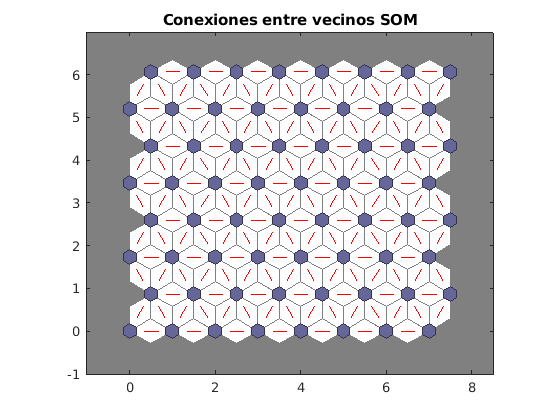

title('Conexiones entre vecinos SOM')

El número de observaciones de entrenamiento que se asocia a cada neurona puede leerse en este gráfico:

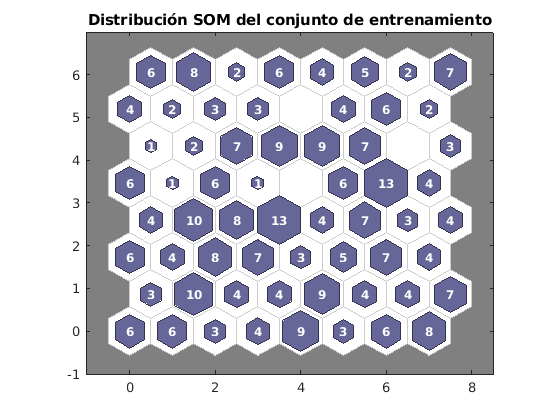

plotsomhits(net,dataTrain)
title('Distribución SOM del conjunto de entrenamiento')

Es imposible determinar con la figura anterior si el mapa auto-organizado logra separar los grupos de los diversos tipos de movimientos considerados en esta fase: movimientos circulares hacia la derecha, circulares hacia la izquierda y movimientos rectilíneos; por lo tanto, los grafico ahora:

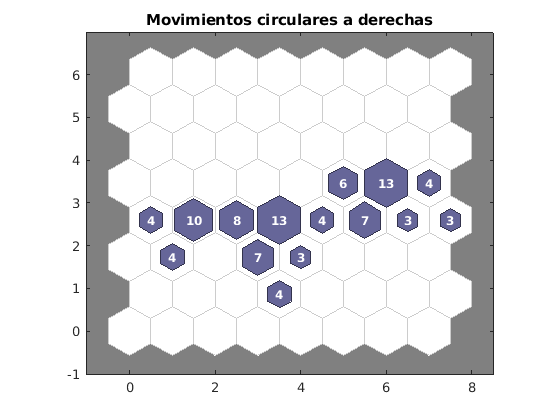

plotsomhits(net,dataTrain(:,tagTrain=='Círculo a dchs.'))
title('Movimientos circulares a derechas')

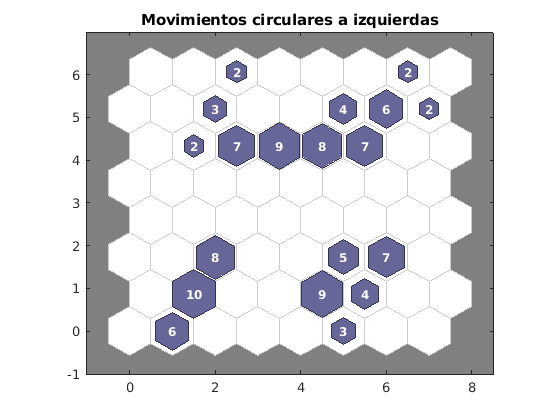


plotsomhits(net,dataTrain(:,tagTrain=='Círculo a izqs.'))
title('Movimientos circulares a izquierdas')


plotsomhits(net,dataTrain(:,tagTrain=='Mov. rectilíneo'))
title('Movimientos rectilíneos')

Se puede discernir una buena separación: movimientos circulares a derechas por el centro, circulares a izquierdas colindates a aquellos y los movimientos rectilíneos en el borde del mapa. Ahora bien, lo ideal es elaborar una matriz de confusión y calcular un porcentaje de error, como hacemos a continuación.

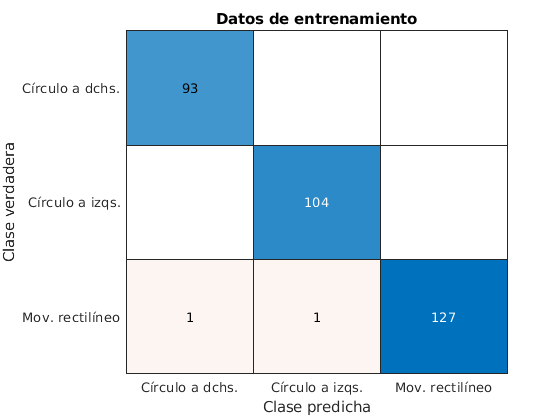

% Diversos cálculos para construir el clasificador a partir del resultado
% del SOM.
classes = vec2ind(net(dataTrain));
counts = countsTable(classes, tagTrain, dimxy);
asignado = counts.Asignado;
predTrain = categorical(asignado(classes));

% Matriz de confusión.
figure()
confusionchart(tagTrain,predTrain,"XLabel","Clase predicha","YLabel","Clase verdadera", ...
    "Title","Datos de entrenamiento")


% Porcentaje de error.
errorTrain = sum(predTrain ~= tagTrain) / length(tagTrain) * 100;
fprintf('El porcentaje de error sobre el conjunto de entrenamiento es: %1.4f%%.', errorTrain)

El porcentaje de error sobre el conjunto de entrenamiento es: 0.6135%.

### Clasificando el conjunto de test

Para verificar realmente lo bueno que es el clasificador, debe estudiarse el error de clasificación en el conjunto de test, como se hace en este trozo de código.

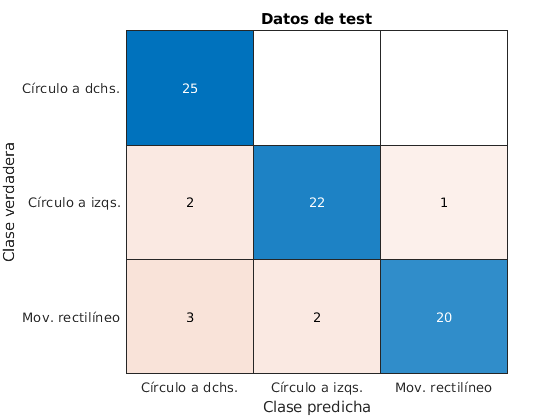

% Diversos cálculos para construir el clasificador a partir del resultado
% del SOM.
classesTest = vec2ind(net(dataTest));
predTest = categorical(asignado(classesTest)); % Usamos el clasificador de entrenamiento.

% Matriz de confusión.
figure()
confusionchart(tagTest,predTest,"XLabel","Clase predicha","YLabel","Clase verdadera", ...
    "Title","Datos de test")


% Porcentaje de error.
errorTest = sum(predTest ~= tagTest) / length(tagTest) * 100;
fprintf('El porcentaje de error sobre el conjunto de test es: %1.4f%%.', errorTest)

El porcentaje de error sobre el conjunto de test es: 10.6667%.

## Discusión

El bajo error de clasificación cometido en entrenamiento muestra que el mapa auto-organizado de Kohonen efectivamente es capaz de separar los tres tipos de movimientos, aunque incurriendo, posiblemente, en algo de sobre-aprendizaje, como lo sugiere el hecho de tener dos órdenes de magnitud más en el error de clasificación sobre el conjunto de test. Ahora bien, el error de clasificación en test está en torno al $10\%$, lo cual es un resultado prometedor, teniendo en cuenta que no he realizado ningún tipo de ajuste de hiperparámetros en el SOM, sino que he aplicado todos los valores por defecto.

Es, quizás, censurable la simplicidad y relativamente alta dimensionalidad de las características usadas en la clasificación de los diferentes tipos de movimiento. En efecto, las características consisten en la concatenación de 40 medidas consecutivas de aceleración en el eje $x$, otras 40 de aceleración en el eje $y$, antes de otras 40 medidas de curvatura. Luego, estoy clasificando vectores de valores reales, de dimensión 120. No obstante, precisamente, esta metodología seguida se estableció así para resaltar la capacidad del SOM en separar patrones de alta dimensionalidad usando simplemente una proyección en dos dimensiones.

Además, con el fin de simular una situación más realista, también registré un nuevo tipo de curva, el "movimiento indefinido". Lo elaboré realizando movimientos ondulantes sobre el plano que no terminaban de cerrarse en un círculo. Repito ahora, escuetamente, el proceso de esta memoria y muestro los resultados en test. Adelanto que el error sobre el conjunto de test se mantiene en torno al $10\%$.

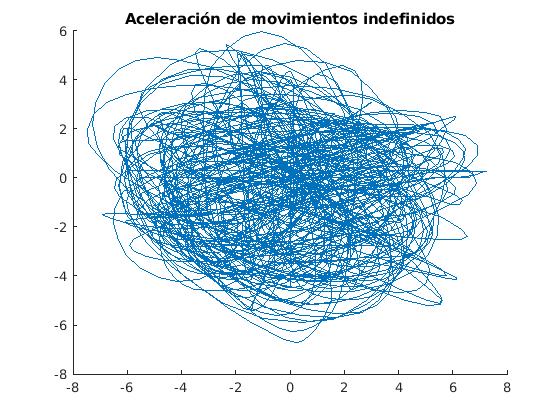

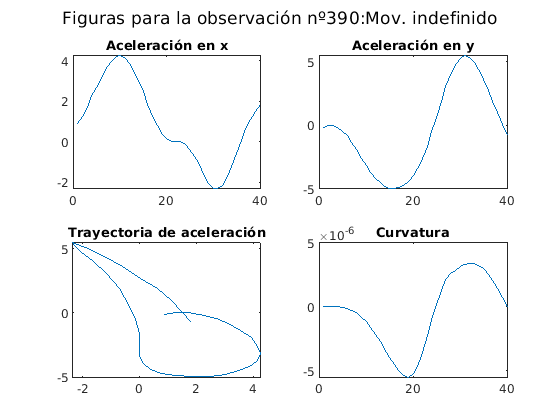

% Conjuntos de curvas a cargar (círculos y rectas). 
s2 = {'CD2', 'CD3', 'CD4', 'CI2', 'CI3', 'CI4', 'R2', 'R3', 'R4', 'R5', 'CR1'};
maxLen2 = 40; % Longitud de cada curva.

% Ejecutamos la función especialmente definida para cargar los datos.
[dataTrain2, tagTrain2, dataTest2, tagTest2] = load_data(s2, maxLen2);

% Aceleración de movimientos indefinidos
figure()
hold on
plotAcceleration('CR1', '-')
title('Aceleración de movimientos indefinidos')
hold off

% Plots de una observación
n = 390;
figure()
plotExample(dataTrain2, tagTrain2, n)

% SOM
net = selforgmap([dimx dimy]);
net = train(net,dataTrain2); % Entrenamiento de la red.

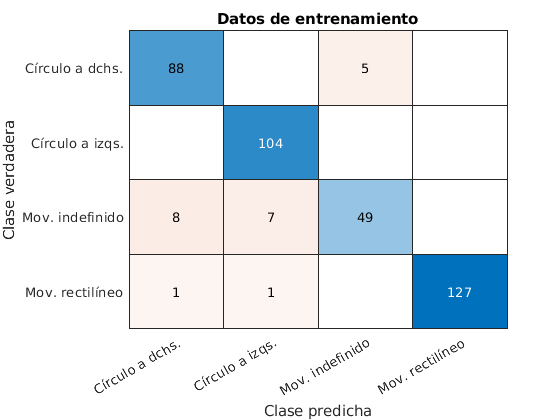


% Diversos cálculos para construir el clasificador a partir del resultado
% del SOM.
classes2 = vec2ind(net(dataTrain2));
counts2 = countsTable(classes2, tagTrain2, dimxy);
asignado2 = counts2.Asignado;
predTrain2 = categorical(asignado2(classes2));

% Matriz de confusión.
figure()
confusionchart(tagTrain2,predTrain2,"XLabel","Clase predicha","YLabel","Clase verdadera", ...
    "Title","Datos de entrenamiento")


% Porcentaje de error.
errorTrain2 = sum(predTrain2 ~= tagTrain2) / length(tagTrain2) * 100;
fprintf('El porcentaje de error sobre el conjunto de entrenamiento es: %1.4f%%.', errorTrain2)

El porcentaje de error sobre el conjunto de entrenamiento es: 5.6410%.

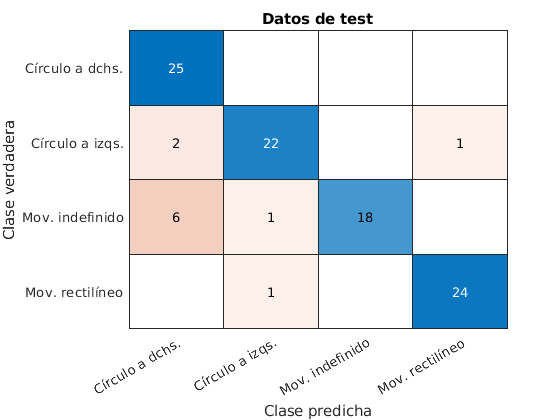


% Diversos cálculos para construir el clasificador a partir del resultado
% del SOM.
classesTest2 = vec2ind(net(dataTest2));
predTest2 = categorical(asignado2(classesTest2)); % Usamos el clasificador de entrenamiento.

% Matriz de confusión.
figure()
confusionchart(tagTest2,predTest2,"XLabel","Clase predicha","YLabel","Clase verdadera", ...
    "Title","Datos de test")


% Porcentaje de error.
errorTest2 = sum(predTest2 ~= tagTest2) / length(tagTest2) * 100;
fprintf('El porcentaje de error sobre el conjunto de test es: %1.4f%%.', errorTest2)

El porcentaje de error sobre el conjunto de test es: 11.0000%.

## Conclusión

He implementado exitosamente un mapa auto-organizado de Kohonen sobre la concatenación de medidas cinemáticas de curvas. También, se ha mostrado la capacidad del mapa auto-organizado de segmentar en el plano un conjunto de datos de muchas dimensiones. Dicha capacidad a quedado cuantificada con los relativamente bajos errores de clasificación en los conjuntos de test de sendos experimentos propuestos (con y sin "movimientos indefinidos").

Para finalizar, quiero hacer énfasis en los aspectos éticos del problema abordado, en lo que concierne al uso de la solución aquí desarrollada para abordar soluciones de accesibilidad para personas con discapacidad, como mencionaba en la introducción. El punto más importante es la fiabilidad de la solución. En efecto, un error en test de entorno al $10\%$puede ser demasiado alta para usarla cómodamente en el manejo de un teléfono móvil o un ordenador, más aún, su uso sería, seguramente, inaceptable como software crítico en el control por parte de una persona con discapacidad de un exoesqueleto. Ahora bien, queda como trabajo futuro un análisis y estudio detallado con el fin de disminuir el error, y desarrollar, por lo tanto, una solución aceptable para aplicaciones de control del teléfono o una computadora.

## Anexo: Funciones

En esta sección se recogen todas las funciones elaboradas para la confección de este trabajo, a saber: 

- `load_data`

- `plotAcceleration`

- `plotExample`

- `countsTable`

function [dataTrain, tagTrain, dataTest, tagTest] = load_data(s, maxLen)
% Esta función carga los datos del acelerómetro del móvil, dividido en
% varios ficheros. Calcula todas las características a usar, guarda cada
% observación en un vector fila y devuelve también un vector columna con la
% etiqueta de cada observación.

% Inicializamos variables.
dataTrain = [];
tagTrain = [];
dataTest = [];
tagTest = [];
data = [];
tag = [];

% Recorremos todos los nombres de datos a cargar.
for i = s
    % Cargamos los datos.
    path = './Data/';
    path = strcat(path, i{:}, '.mat');
    load(path, 'Acceleration')
    
    % Extraemos aceleración en eje x y eje y.
    ax = Acceleration.X;
    ay = Acceleration.Y;
    
    % Cada ```maxLen``` posiciones, hace una observación.
    len = length(ax);
    maxIter = fix(len/maxLen);
    
    % Iteramos extrayendo observaciones.
    for j = 2:(maxIter-2)
        % Índices de partición.
        id1 = j * maxLen;
        id2 = (j + 1) * maxLen - 1;
        
        % Componentes.
        comp1 = ax(id1:id2)';
        comp2 = ay(id1:id2)';
        vx = cumtrapz(comp1); % Velocidad en x.
        vy = cumtrapz(comp2); % Velocidad en y.
        comp3 = (vx.*comp2-comp1.*vy)/(dot(vx,vx)+dot(vy,vy))^(3/2); % Curvatura.
        
        % Registramos las observaciones.
        data = [data; cat(2, comp1, comp2, comp3)];
        
        % Escribimos la etiqueta que le corresponde a cada observación.
        auxTag = i{:};
        tag = [tag; {auxTag(1:(end - 1))}];
    end    
end

% Convertimos a categórico.
tag = categorical(tag);

% Renombramos las categorías
category = string(categories(tag));
if any(strcmp(category,'CD'))
    tag = renamecats(tag, 'CD', 'Círculo a dchs.');
end
if any(strcmp(category,'CI'))
    tag = renamecats(tag, 'CI', 'Círculo a izqs.');
end
if any(strcmp(category,'R'))
    tag = renamecats(tag, 'R', 'Mov. rectilíneo');
end
if any(strcmp(category,'CR'))
    tag = renamecats(tag, 'CR', 'Mov. indefinido');
end

% Creamos los conjuntos de entrenamiento y test.

% Contador.
i = 0;

% Convertimos a cadena.
tag = string(tag);

% Categorías
category = string(categories(categorical(tag)));

% Número de observaciones por categoría
for j = 1:length(category)
    
    % Número de observaciones en la categoría.
    amount = sum(strcmp(tag,category(j)));
    
    % Rellenamos.
    dataTrain = [dataTrain; data((i+1):(i+amount-25),:)];
    tagTrain = [tagTrain; tag((i+1):(i+amount-25))];
    dataTest = [dataTest; data((i+amount-24):(i+amount),:)];
    tagTest = [tagTest; tag((i+amount-24):(i+amount))];
    
    % Aumentamos el contador.
    i = i + amount;
end

% Hay que trasponer las variables ```data```
dataTrain =  dataTrain';
tagTrain =  categorical(tagTrain);
dataTest = dataTest';
tagTest = categorical(tagTest);

end

function plotAcceleration(s, opts)
% Esta función hace un plot de las aceleraciones en el plano. Toma como
% variable ```s``` el archivo a cargar. La variable ```òpts``` son las
% opciones propias del comando ```plot```.

% Cargamos los datos.
path = './Data/';
path = strcat(path, s, '.mat');
load(path, 'Acceleration')

% Extraemos aceleración en eje x y eje y.
ax = Acceleration.X;
ay = Acceleration.Y;

% Hacemos el plot
plot(ax, ay, opts)
end

function plotExample(data, tag, n)
% Esta función dibuja la aceleración de x, de y, la trayectoria de las
% aceleraciones y la curvatura de la trayectoria ```n```-ésima contenida en
% la variable ```data```.

% Extraemos los datos de la trayectoria ```n```-ésima
ax = data(1:40,n)';
ay = data(41:80,n)';
c = data(81:120,n)';

% Graficamos la aceleración en x
subplot(2,2,1);
plot(ax)
title('Aceleración en x')

% Graficamos la aceleración en y
subplot(2,2,2);
plot(ay)
title('Aceleración en y')

% Graficamos la trayectoria de la aceleración
subplot(2,2,3);
plot(ax, ay)
title('Trayectoria de aceleración')

% Graficamos la curvatura
subplot(2,2,4);
plot(c)
title('Curvatura')

% Título global
s = 'Figuras para la observación nº ';
name = string(tag(n));
n = string(n);
s = strcat(s, n, ': ', name);
sgtitle(s)
end


function counts = countsTable(class, tag, dim)
% Esta función devuelve una tabla que enfrenta cada neurona con las cuentas
% de las categorías que se clasfican en ella. Por ejemplo, para cada
% neurona devuelve una información del tipo:
% | Neurona | Círculo a dchs. | Círculo a izqs. | Mov. rectilíneo | Mov. indefinido |
% |:-------:|:---------------:|:---------------:|:---------------:|:---------------:|
% |    1    |        10       |        0        |        0        |        0        |
% |    2    |        0        |        0        |        1        |        5        |
%

% Vector de categorías
category = string(categories(tag))';

% Inicializamos la tabla
len = length(category);
sz = [dim (len+2)];
varTypes = ["double",repmat(["double"],[1,len]),"string"];
varNames = ["Neurona",category,"Asignado"];
counts = table('Size',sz,'VariableTypes',varTypes,'VariableNames',varNames);

% Recorremos las neuronas, rellenando la tabla
for k = 1:dim
    idx = (class == k);
    amounts = reshape(countcats(tag(idx)),1,len);
    counts(k,1:(len+1)) = num2cell([k, amounts]);
    [~,maxIdx]=max(amounts);
    counts(k,(len+2)) = {category(maxIdx)};
end

end